# Tracking Mode Data Processing

### 初始化

clc;
clear

### 参数设置

M = 7.50E3;
Fs = 15E6;
pathname = 'sw0.xlsx';

### 数据读取

wave_data = readmatrix(pathname)

wave_data =     0.2064    1.5796
    0.2556    1.5281
    0.3118    1.4719
    0.3702    1.4104
    0.4329    1.3476
    0.4994    1.2809
    0.5678    1.2100
    0.6396    1.1381
    0.7114    1.0645
    0.7858    0.9909


vout = wave_data(1:M,1) - wave_data(1:M,2);

### 绘制时域波形图

T = PhaseOrder(vout, 200E3, Fs)

T = 7500×3 table
    Index     Value     PhaseOrder
    _____    _______    __________

      75     -1.4663        0     
     150     -1.4664        0     
     225     -1.4674        0     
     300     -1.4676        0     
     375     -1.4662        0     
     450     -1.4654        0     
     600     -1.4694        0     
     675     -1.4698        0     
     750     -1.4685        0     
     825     -1.4688        0     
     900     -1.4678        0     
     975     -1.4687        0     
    1200     -1.4686        0     
    1275     -1.4666        0     
    1350     -1.4663        0     
    1425     -1.4659        0     


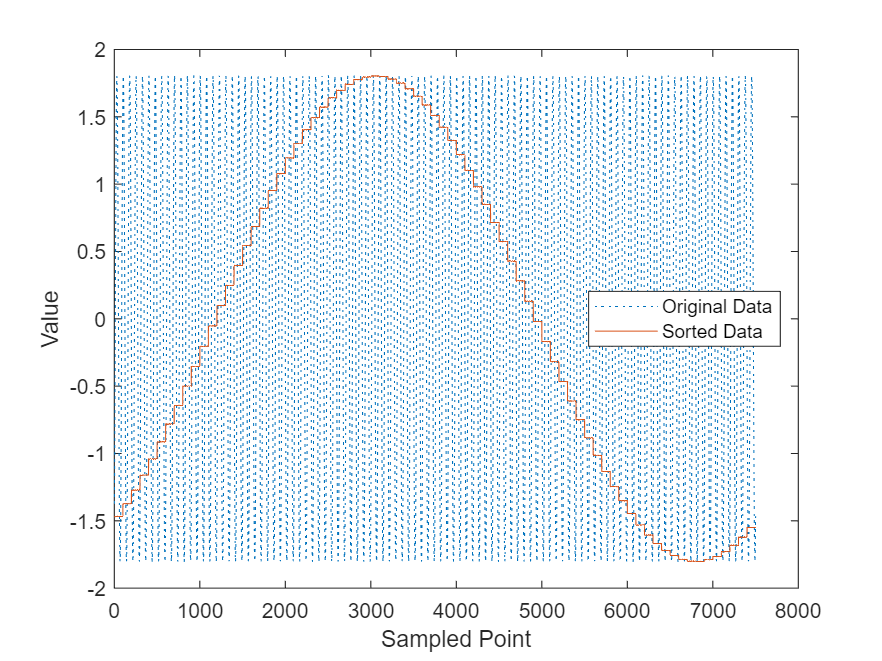

figure
plot(vout, ":");
hold on
plot(T.Value);
hold off
xlabel("Sampled Point");
ylabel("Value");
legend(["Original Data", "Sorted Data"], "Location","best");

### 计算THD

figure
[r,harmpow,harmfreq] = thd(vout, Fs, 9, 'aliased')

r = -67.5952

harmpow =     2.1042
  -66.6148
  -71.9240
 -103.4716
 -106.1269
 -107.5131
 -106.6272
 -105.6565
 -103.5909


harmfreq = 	1.0e+06 *

    0.2000
    0.4000
    0.6000
    0.7980
    1.0000
    1.1980
    1.3980
    1.6020
    1.7980


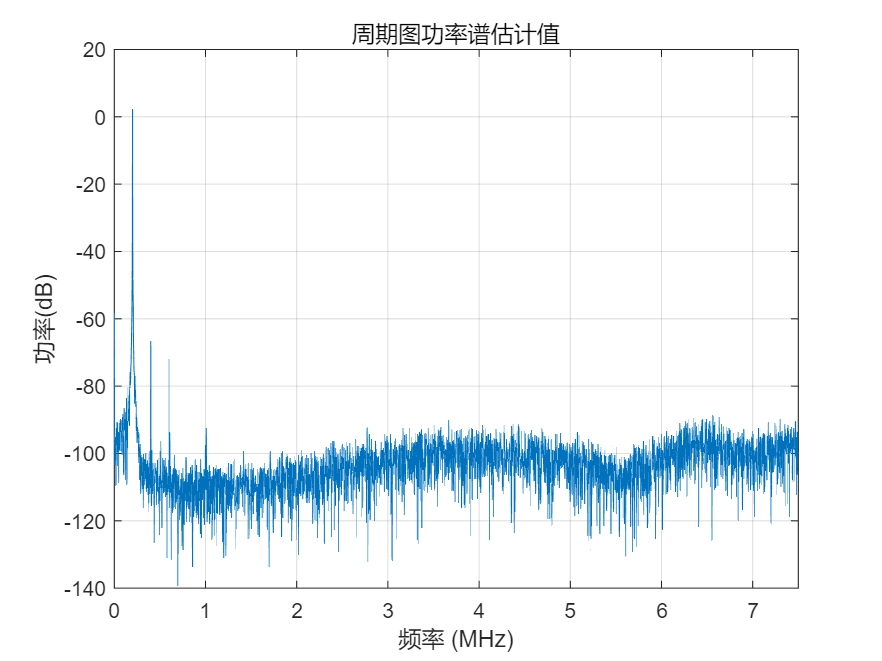

periodogram(vout, kaiser(M), M, Fs, "onesided", "power")

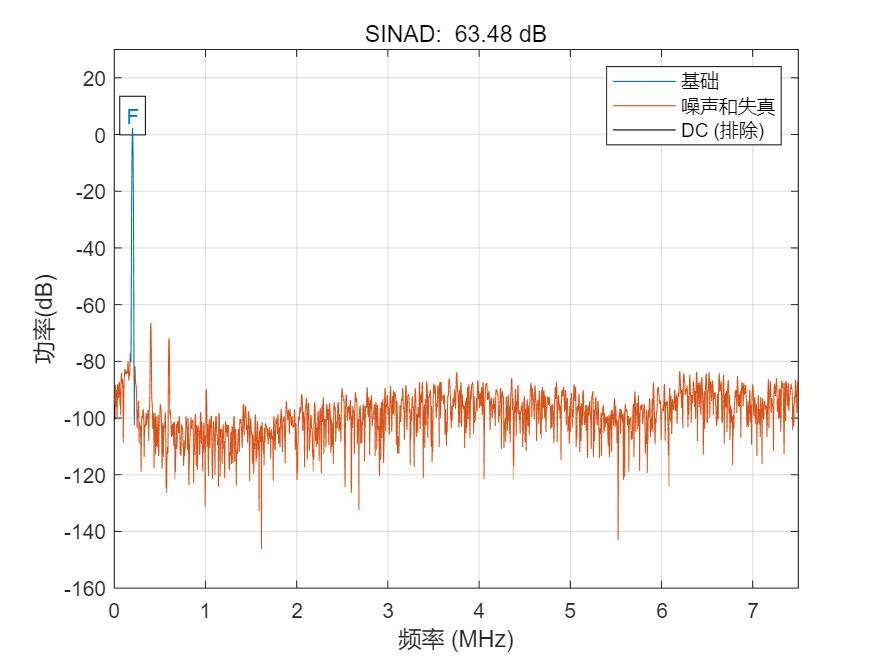

ans = 63.4816

sinad(vout,Fs)

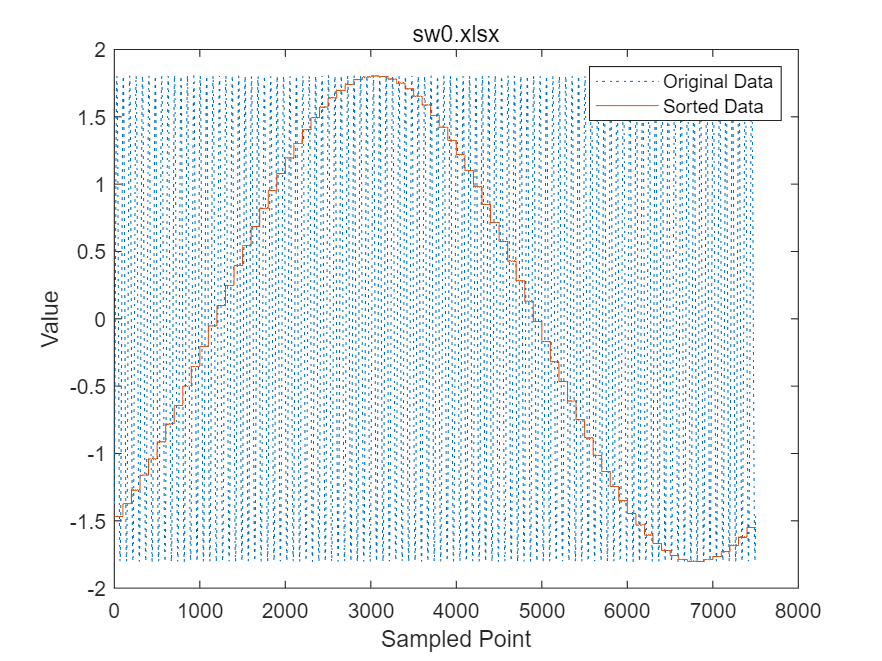

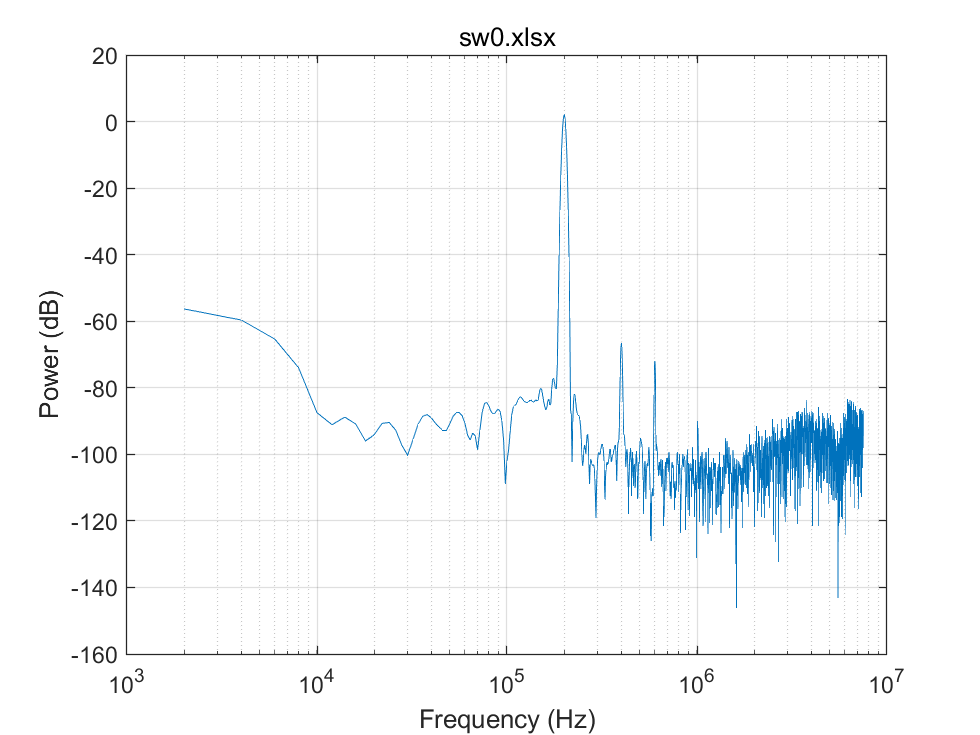

Data = 7500×3 table
    Index     Value     PhaseOrder
    _____    _______    __________

      75     -1.4663        0     
     150     -1.4664        0     
     225     -1.4674        0     
     300     -1.4676        0     
     375     -1.4662        0     
     450     -1.4654        0     
     600     -1.4694        0     
     675     -1.4698        0     
     750     -1.4685        0     
     825     -1.4688        0     
     900     -1.4678        0     
     975     -1.4687        0     
    1200     -1.4686        0     
    1275     -1.4666        0     
    1350     -1.4663        0     
    1425     -1.4659        0     


THD = -67.5952

distortion = 9×2 table
    Frequency      Power 
    __________    _______

         2e+05     2.1042
    3.9999e+05    -66.615
         6e+05    -71.924
      7.98e+05    -103.47
         1e+06    -106.13
     1.198e+06    -107.51
     1.398e+06    -106.63
     1.602e+06    -105.66
     1.798e+06    -103.59


[Data, THD, distortion] = TrackingModeProcess('sw0.xlsx', 7500, 200E3, 15E6)

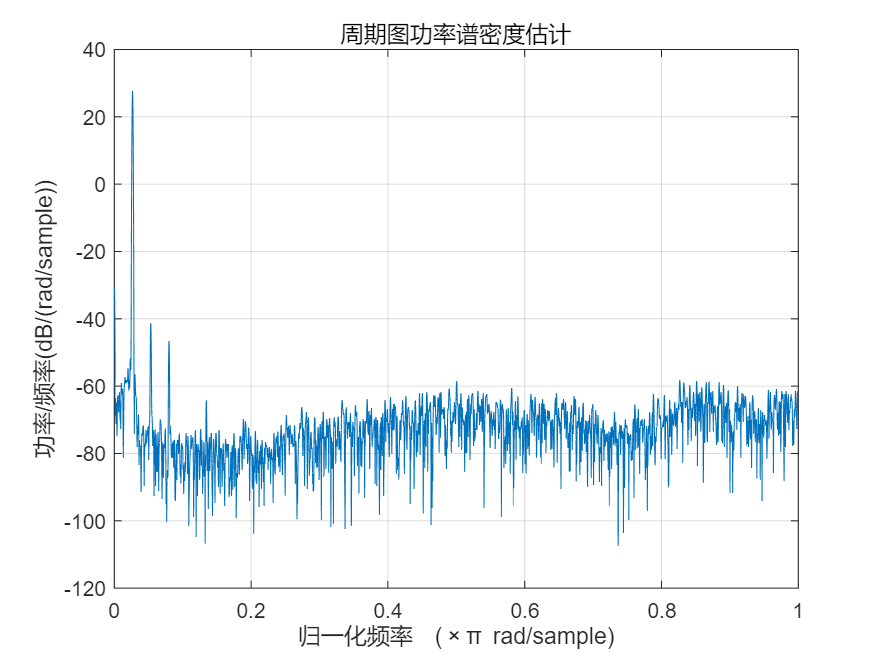

periodogram(vout, kaiser(length(vout), 38))

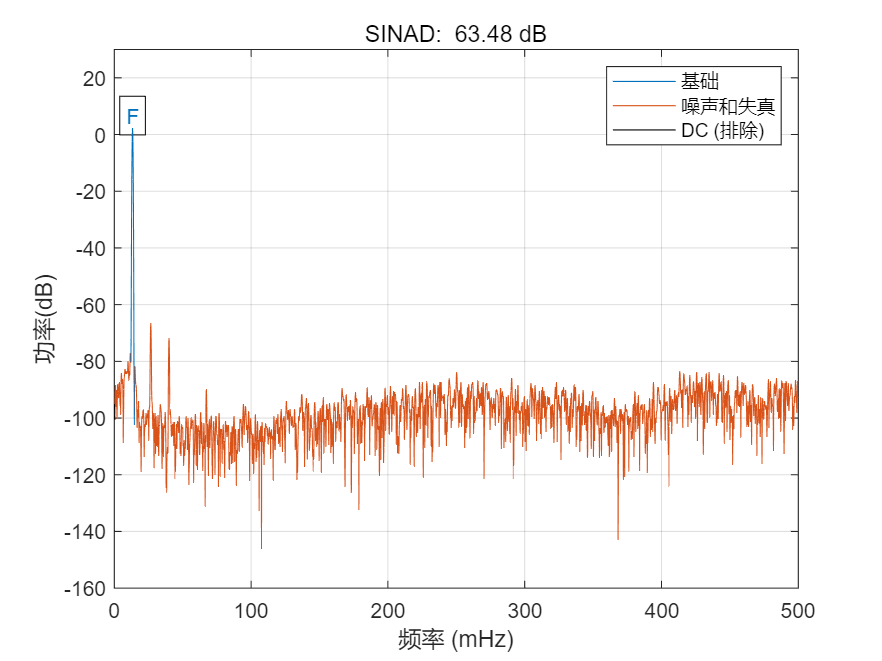

ans = 63.4816

sinad(vout)